# 1-D Gaussian Process Regression

This script provides a visual demonstration of the fundamental principles of Gaussian Process Regression (GPR). GPR is a powerful, non-parametric Bayesian method capable of modeling complex, non-linear functions.

### Step 1: Data Generation

First, we generate the data that will be used for training and predicting with our GPR model.

- **Observed Data:** We start by defining an unknown target function. Here, we combine `sin` and `cos` terms to create a complex, non-linear function. From this function, we randomly select 20 points to serve as our **"observed data" **for training the GPR. In a real-world scenario, these observations would be the only information we have.

- **Prediction Range:** We define a dense range of x-coordinates where we want the GPR to predict the function's value. The GPR will estimate the mean and variance of $y$ for each of these points.

- **Noise Parameter:** The GPR model assumes that the observations may contain noise. The parameter $\sigma_{noise}$ represents the standard deviation of this assumed noise.

% Data Generation
x_range = linspace(0, 10, 100);                     % Create 100 x-coordinates between 0 and 10
x_obs_indices = randperm(length(x_range), 20);      % Randomly select training data (observed data)
x_obs = x_range(x_obs_indices)';                    % Get the x-coordinates for the selected indices

sigma_noise = 0.8;                                    % Noise standard deviation parameter 

% Create y_obs from a complex function WITH ADDED NOISE
y_obs = 10 * sin(15 * x_obs/10) + 3 * cos(20 * x_obs/10) + sigma_noise * randn(size(x_obs));

### **Step 2: Kernel Function Definition**

The core of a Gaussian Process is the kernel function. The kernel defines the similarity (covariance) between data points and, in doing so, determines the overall characteristics of the function, such as its smoothness.

Here, we use the most common kernel, the Squared Exponential (SE) kernel, also known as the Radial Basis Function (RBF) kernel. Its formula is: $k(x_i, x_j) = \sigma_f^2 \exp\left(-\frac{1}{2l^2}(x_i - x_j)^2\right)$

- $\sigma_f^2$: The signal variance. This hyperparameter controls the maximum expected vertical variation of the function.

- $l$: The length-scale. This hyperparameter controls the smoothness of the function. A larger value results in a smoother function, while a smaller value allows for more rapid variations.

Using this kernel function, we compute the following three covariance matrices:

- $K$: The covariance matrix between the observed data points $x_{obs}$  and themselves.

- $K_s$: The covariance matrix between the observed data $x_{obs}$ and the prediction points $x_{test}$.

- $K_{ss}$: The covariance matrix between the prediction points $x_{test}$ and themselves.

% Create a dense set of points for test point
x_test = linspace(0, 10, 200)'; 

% Kernel function definition (e.g., RBF kernel)
sigma_f = 3;
l = 1.0; % Adjusting the length-scale to cover a wider range

K = sigma_f^2 * exp(-0.5 * pdist2(x_obs, x_obs).^2 / l^2);
K_s = sigma_f^2 * exp(-0.5 * pdist2(x_obs, x_test).^2 / l^2);
K_ss = sigma_f^2 * exp(-0.5 * pdist2(x_test, x_test).^2 / l^2);

### **Step 3: Gaussian Process Regression Calculation**

GPR assumes that the observed values, $y$, and the values to be predicted, $y_*$, follow a joint Gaussian distribution: $$$\left[ \begin{array}{c} y \\ y_* \end{array} \right] \sim \mathcal{N} \left( 0, \left[ \begin{array}{cc} K + \sigma_{noise}^2 I & K_s \\ K_s^T & K_{ss} \end{array} \right] \right)$$$

What we want is the conditional probability distribution $p(y_* | x_{pred}, x_{obs}, y_{obs})$, which is also a Gaussian distribution. Its mean and variance can be derived as follows:

- **Posterior Mean:**$$\bar{y}_{pred} = K_s^T (K + \sigma_{noise}^2 I)^{-1} y_{obs}$ \quad (Assume zero-mean)$

- **Posterior Variance:**$$\text{cov}(y_{pred}) = K_{ss} - K_s^T (K + \sigma_{noise}^2 I)^{-1} K_s$$

In the code, instead of directly computing the matrix inverse $(K + \sigma_{noise}^2 I)^{-1}$, we use Cholesky Decomposition $L=\text{cholesky}(K + \sigma_{noise}^2 I)$, which is a more numerically stable and efficient method for this calculation.

% Gaussian Process Regression calculation
K_y = K + sigma_noise^2 * eye(length(x_obs));
L = chol(K_y, 'lower');
alpha = L' \ (L \ y_obs);

% Calculate predictive mean and variance
y_pred_mean = K_s' * alpha;
v = L \ K_s;
y_pred_var = K_ss - v' * v;
y_pred_std = sqrt(diag(y_pred_var));

### **Step 4: Result Visualization**

Finally, we visualize the results to inspect the performance of the GPR model.

- **Black Crosses (**`Observed Data Points`**):** These are the few data points that we had access to for training.

- **Red Line (**`Estimated Function`**):** This is the predictive mean of the GPR $\bar{y}_{pred}$. Note how the line passes smoothly through the observed points.

- **Blue Shaded Area (**`95% Confidence Interval`**):** This area represents the 95% confidence interval of the prediction $$\bar{y}_{pred} \pm 2 \cdot \sqrt{\text{diag}(\text{cov}(y_{pred}))}$$. It visualizes the GPR's "uncertainty." It is narrowest near the observed data points, where the model is confident, and becomes wider in regions far from any observations, correctly reflecting the lack of information there.

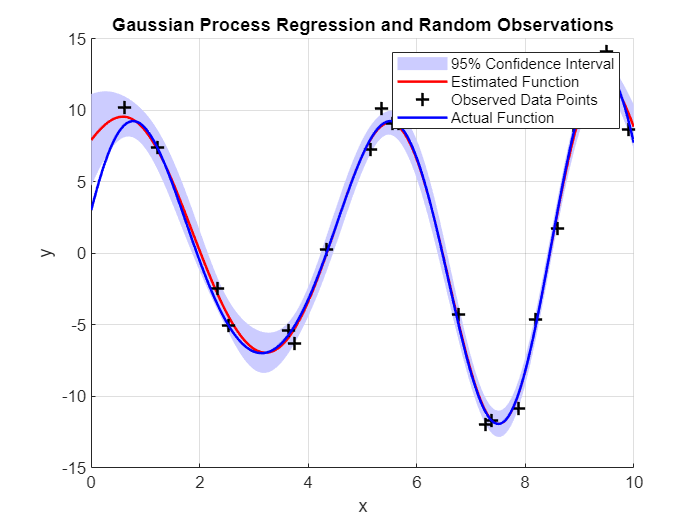

% Plot the graph
figure;
hold on;
fill([x_test; flipud(x_test)], [y_pred_mean + 2*y_pred_std; flipud(y_pred_mean - 2*y_pred_std)], ...
    [0.8 0.8 1], 'EdgeColor', 'none'); % Visualize the 95% confidence interval
plot(x_test, y_pred_mean, 'r-', 'LineWidth', 1.5); % Plot the estimated function
plot(x_obs, y_obs, 'k+', 'MarkerSize', 8, 'LineWidth', 1.5); % Plot the observed data points
y_actual = 10 * sin(15 * x_test/10) + 3 * cos(20 * x_test/10); % Create an actual value at test input points
plot(x_test, y_actual, 'b-', 'LineWidth', 1.5); % Plot the Actual Function

legend('95% Confidence Interval', 'Estimated Function', 'Observed Data Points','Actual Function');
xlabel('x');
ylabel('y');
title('Gaussian Process Regression and Random Observations');
grid on;
hold off;